# Phase-lead compensator to explain phase-leading behavior in *Drosophila* head movements

clear; close all; clc
syms s I c k K_p K_d K_i a_2 tau K
assume([I c k s]>=0)
assume([I c k],'real')

## Contol Framework

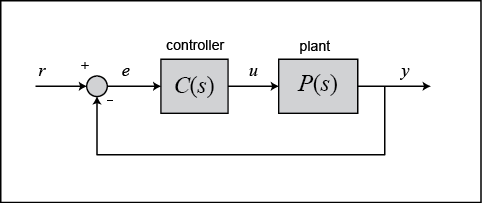

### Plant

P(s) = 1/(I*s^(2) + c*s + k)

$$P(s) = \frac{1}{\text{I}\,s^{2}+c\,s+k}$$

### Controller

% C(s) = K_p + K_d*s + K_i*(1/s)
K = 1;
C_1(s) = K + s*0

$$C\_1(s) = 1$$

C_2(s) = (a_2*tau*s + 1)/(tau*s + 1)

$$C\_2(s) = \frac{a_{2}\,s\,\tau +1}{s\,\tau +1}$$

C(s) = C_1(s)*C_2(s);

### Closed-Loop Model

G(s) = collect(simplify(P(s)*C(s)/(1 + P(s)*C(s))),s)

$$G(s) = \frac{\left(a_{2}\,\tau \right)\,s+1}{\left(\text{I}\,\tau \right)\,s^{3}+\left(\text{I}+c\,\tau \right)\,s^{2}+\left(c+a_{2}\,\tau +k\,\tau \right)\,s+k+1}$$

### Error Model

H(s) = collect(simplify(expand(1/(1+P(s)*C(s)))),s)

$$H(s) = \frac{\left(\text{I}\,\tau \right)\,s^{3}+\left(\text{I}+c\,\tau \right)\,s^{2}+\left(c+k\,\tau \right)\,s+k}{\left(\text{I}\,\tau \right)\,s^{3}+\left(\text{I}+c\,\tau \right)\,s^{2}+\left(c+a_{2}\,\tau +k\,\tau \right)\,s+k+1}$$

Ess = limit(s*H(s),s,0)

$$Ess = \left\{ \begin{array}{cl} -\frac{1}{c-\tau +a_{2}\,\tau } & \text{ if }k=-1\\ 0 & \text{ if }k\neq -1 \end{array}\right.$$

## Plant Paramters

Natural Frequency (rad/s)

wn = 50;

Damping Ratio

z = 1.2;

Head inertia about rotation point (kg*m^2)

I_num = 1;

Head stiffness (N*m/rad)

k_num = wn^(2)*I_num;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(k_num*I_num);

Head damping (N*m*s/rad)

c_num = z*cc;

## Controller Paramters

wm = 1;
phase_add = deg2rad(40);
a_2_num = double(solve(phase_add == asin((a_2-1)/(a_2+1))))

a_2_num = 4.5989

tau_num = 1/(wm*sqrt(a_2_num))

tau_num = 0.4663

## Numeric Model

P_num = simplify(subs(P(s),[I c k],[I_num c_num k_num]))

$$P\_num = \frac{1}{s^{2}+120\,s+2500}$$

C_num = vpa(simplify(subs(C(s),[a_2 tau] , [a_2_num tau_num])),3)

$$C\_num = \frac{2.14\,s+1.0}{0.466\,s+1.0}$$

% vpa(simplify(P_num*C_num/(1+P_num*C_num)),3)
G_num =  vpa(simplify(subs(G(s),[I c k , a_2 tau],[I_num c_num k_num , a_2_num tau_num])));
H_num =  vpa(collect(simplify(subs(H(s),[I c k , a_2 tau],[I_num c_num k_num , a_2_num tau_num])),s));
s*H_num;
Ess = limit(s*H_num,s,0)

$$Ess = 0.0$$

H_tf = sym2tf(H_num)


H_tf =
 
  5.911e29 s^3 + 7.22e31 s^2 + 1.63e33 s + 3.169e33
  -------------------------------------------------
  5.911e29 s^3 + 7.22e31 s^2 + 1.633e33 s + 3.17e33
 
Continuous-time transfer function.



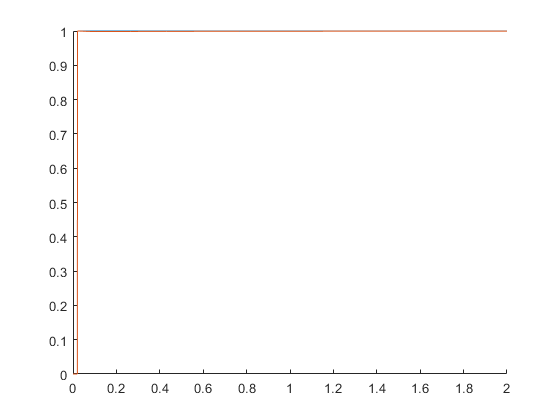

tt = (0:0.001:2)';
n = length(tt);
u = ones(n,1);
u(tt<=0.02) = 0;
[y,t,x] = lsim(H_tf,u,tt);
hold on
plot(t,u)
plot(t,y)

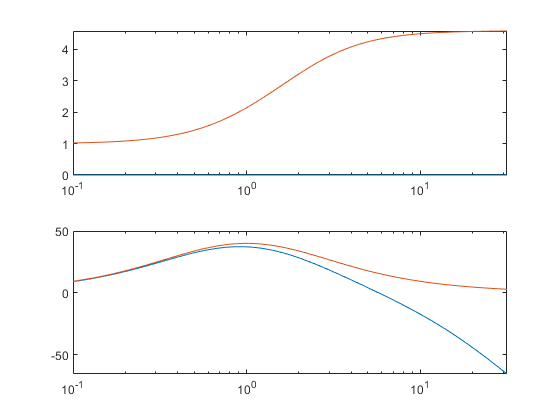


[mag,phase,freq] = bode(sym2tf(G_num),logspace(-1,2,1000));
figure (1) ; clf
ax(1) = subplot(2,1,1);
semilogx(freq,squeeze(mag)) ; hold on
% ylim([0 1])
ax(2) = subplot(2,1,2);
semilogx(freq,squeeze(phase)) ; hold on
set(ax,'XLim',10.^[-1 1.5])

[mag,phase,freq] = bode(sym2tf(C_num),logspace(-1,2,1000));
ax(1) = subplot(2,1,1);
semilogx(freq,squeeze(mag))
ax(2) = subplot(2,1,2);
semilogx(freq,squeeze(phase))
set(ax,'XLim',10.^[-1 1.5])

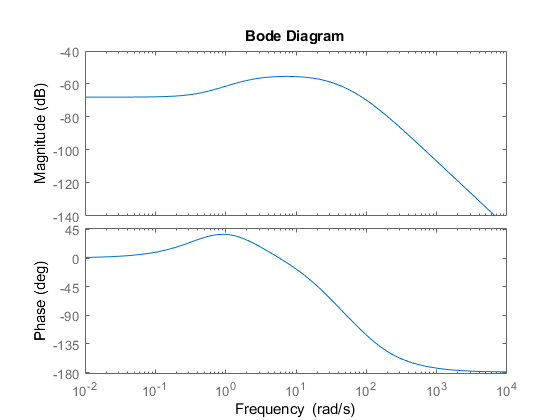

figure (2) ; clf
bode(sym2tf(G_num))